clear;

N = 13; % Janela (número de amostras) da regressão
M = 130; % Janela da média móvel
D = 10; % Distância entre amostras da regressão
thr = 0.474;
extra = 0; % Valor adicionado ao tempo de amaciamento para deixar mais conservador [h]
minT = 10; % Número mínimo de horas considerado por ensaio (normalmente é 2*tEst)
wMax = 2; % Duração máxima da janela [h];


load('EnDataA.mat');

conjVal = [1,1;4,2;5,3]; % Ensaios reservados para conjunto de validação [Amostra, ensaio]

% Tempos de amaciamento esperados:

tEst{1} = 4.4;

tEst{2} = [7.5;
           2.5;
           2.5;
           2.5];
       
tEst{3} = [11.8;
           2.5;
           2.5];
         
tEst{4} = [6;
           2.5;
           2.5;
           2.1];

tEst{5} = [12.5;
           2.5;
           2.5];

       
for k1 = 1:size(conjVal,1) % Apaga os valores dos conjuntos de validação
    EnTest{conjVal(k1,1)}(conjVal(k1,2)) = EnData{conjVal(k1,1)}(conjVal(k1,2));
    tEstTest{conjVal(k1,1)}(conjVal(k1,2)) = tEst{conjVal(k1,1)}(conjVal(k1,2));
    tEst{conjVal(k1,1)}(conjVal(k1,2)) = [];
    EnData{conjVal(k1,1)}(conjVal(k1,2)) = [];
end
       

[Xobs,Yres] = preTrain(EnData,tEst,N,M,D,minT);

rng(10); % Fixed random seed generator

Lambda = 10^(-2.33);
kFold = 50;
Mdl = treinaModeloFitCL(Xobs,Yres,kFold,Lambda);
yPred = cell(1,length(Mdl.Trained));
[XTest,YTest] = preTrain(EnTest,tEstTest,N,M,D,minT);
for k = 1:length(Mdl.Trained)
    yPred{k} = predict(Mdl.Trained{k},XTest);
end
yPred=cell2mat(yPred);
yPred = sum(yPred,2);


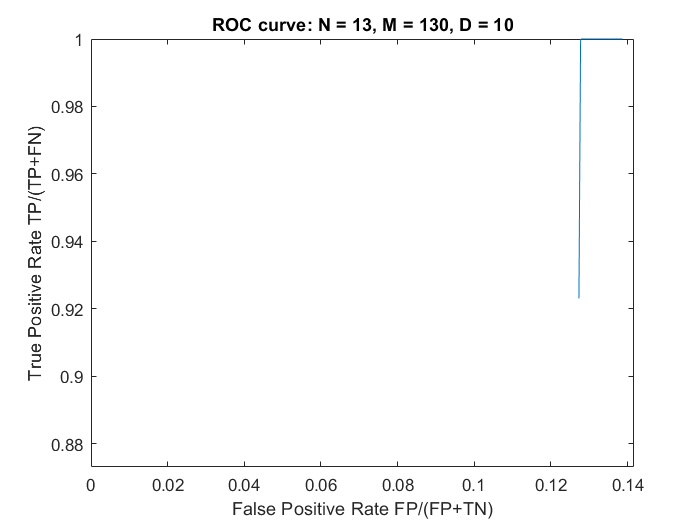

figure;
thrV = 1:kFold;
for k = 1:length(thrV)
    gtest = yPred>=thrV(k);
    cMat = confusionmat(YTest,gtest);
    TPR(k) = cMat(1,1)/sum(cMat(:,1));
    FPR(k) = cMat(1,2)/sum(cMat(:,2));
end
p = plot(FPR,TPR); xlim([0 1]); ylim([0 1]);
row = dataTipTextRow('Thr',thrV);
p.DataTipTemplate.DataTipRows(end+1) = row;
ylabel('True Positive Rate TP/(TP+FN)');
xlabel('False Positive Rate FP/(FP+TN)');
xlim([0 max(FPR)]); ylim([min(TPR)-0.05 1]);
title(['ROC curve: N = ',num2str(N),', M = ',num2str(M),', D = ',num2str(D)]); 

% dcm_obj = datacursormode();
% createDatatip(dcm_obj, p, [TPR(thrV == thr),FPR(thrV == thr)]);
% dt = datatip(p,FPR(thrV == thr),TPR(thrV == thr));